
clc
close
clear

loadIn = load('C:\Users\v.krueger\MATLAB Drive\John Studies Drive\data\exampleData.mat');
loadContactLT = load('C:\Users\v.krueger\MATLAB Drive\John Studies Drive\data\exampleContact.mat');

% data = loadIn.
data = loadIn.tempRaw_Signal;
contactLT = loadContactLT.tempRawContact_Signal;
contactLT = contactLT/1000;
stepData = data;

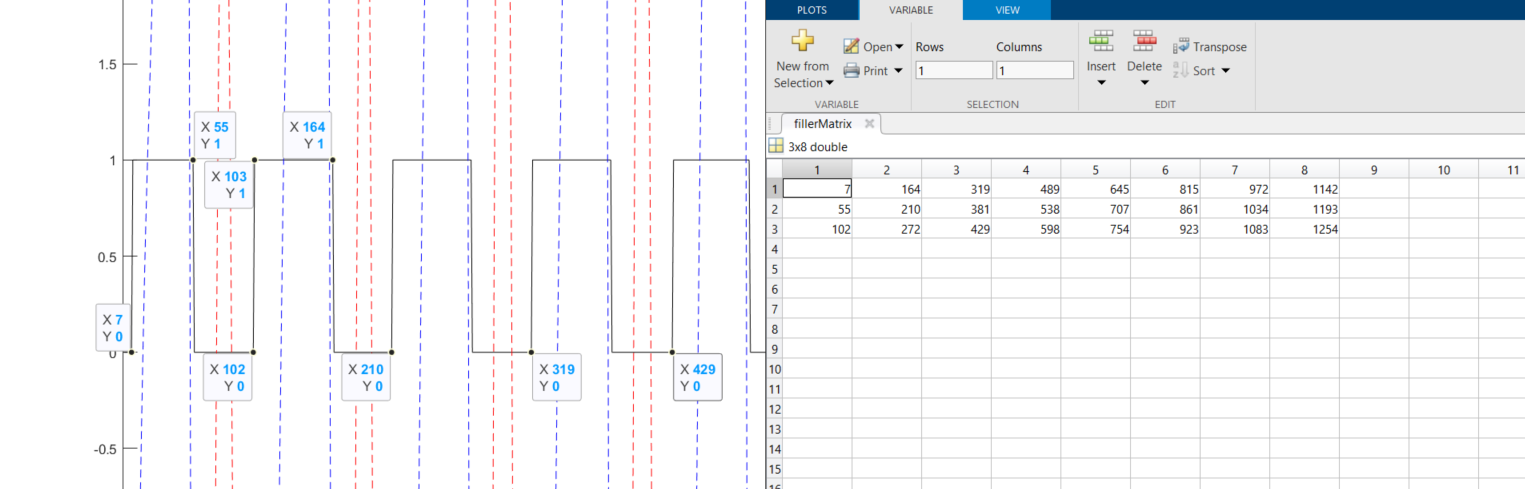

[ind , x] = find(contactLT==0);
[ind2, x2] = find(contactLT);
contactData = contactLT;


stepData2 = data;
stepData2(ind2) = NaN; %Data where toeOff (ipsilateral)
stepData(ind) = NaN;  %Data where HeelStrike (ipsilateral)

%counter to iterate through the Gait Cycle
stepCounter = 1;
%state of the Gait Cycle
initial_FootContact = 1;
toeOff_FootContact = 2;
nextInitial_FootContact =3;
%count the number of completed Gait Cycles
cycle_Phase_Counter =0;
cycle_Counter = 0;
%Vector to save indices
fillerVector = zeros(3,1);
%NewIndicesCounter
oldMarker = 0;
newMarker = 0;
intervals=[];
%Matrix for each foot Contact;
fillerMatrix = [];

% stepData(contactLT==0) = newContact
for i = 1:length(stepData)-1
    %we enter a phase change of contact here from either 0  to  1 or from
    intervals = find_intervals(contactData);
    %1 to 0, as given by the contactData
    % if (contactData(i) + contactData(i+1)) == 1
    %     if contactData(i+1) == 1
    %         cycle_Phase_Counter = cycle_Phase_Counter+1;
    % 
    %         %first step is track individually.
    %         %odd numbers will mean heel strike as well, but also saves
    %         if cycle_Phase_Counter == 1
    %             disp("first Step")
    %             disp(i);
    %         %even numbers means that toeOff was performed - Cycle ends here    
    %         else
    %             fprintf("this is step no. %s", string(cycle_Phase_Counter));
    %             disp(i);
    %             %condition for last cycle_phase_counter? if counter=12,
    %             %there are max. 11 strides
    %         end
    % 
    % 
    %     end
        % cycle_Phase_Counter = cycle_Phase_Counter+1;
        % fillerVector(cycle_Phase_Counter) = i;
        % if mod(cycle_Phase_Counter,3) == 0
        % cycle_Counter = cycle_Counter+1;
        % fillerMatrix(:,cycle_Counter) = fillerVector;
        % cycle_Phase_Counter = 0;
        % end

    % end
end



## Normalize here

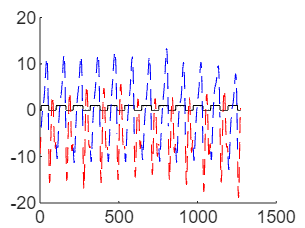

figure;
% plot(data,'r--');
hold on;
plot(contactLT,'k');
plot(stepData2,'r--');
plot(stepData,'b--');

hold off;